syms u(t) v(t)

ode1 = diff(u) == 3*u + 4*v;
ode2 = diff(v) == -4*u + 3*v;
cond1 = u(0) == 0;
cond2 = v(0) == 1;

odes = [ode1; ode2];
conds = [cond1; cond2];

t = 1:1:10

t =      1     2     3     4     5     6     7     8     9    10


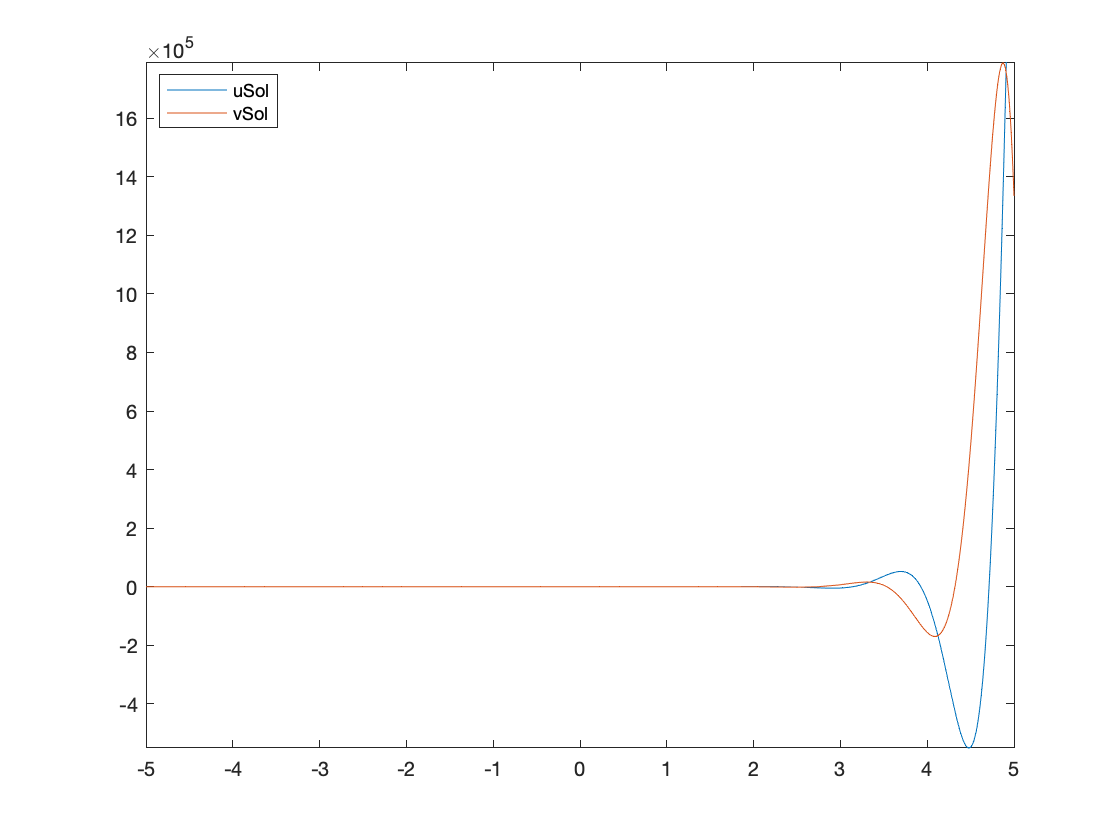


[uSol, vSol] = dsolve(odes, conds);

fplot(uSol);
hold on;
fplot(vSol);
legend('uSol', 'vSol', 'Location', 'best');